clear;
clc;

% Constants
N = 100; % Number of time steps
T = 1; % Sampling time

% State density parameters
x_0 = [0; 0; 20; 0; 5*pi/180];
P_0 = diag([10^2, 10^2, 2^2, (pi/180)^2, (pi/180)^2]);

% Dual bearing measurement model parameters
s1 = [-200; 100];
s2 = [-200; -100];

% Measurement noise standard deviations for Case 1
choice = 3;

switch choice
    case 1
        sigma_v = 1;
        sigma_w = pi/180;
        sigma_phi1 = 2*pi/180;
        sigma_phi2 = 2*pi/180;
    case 2
        sigma_v = 1;
        sigma_w = pi/180;
        sigma_phi1 = 2*pi/180;
        sigma_phi2 = 0.1*pi/180;
    case 3
        sigma_v = 1;
        sigma_w = pi/180;
        sigma_phi1 = 0.1*pi/180;
        sigma_phi2 = 0.1*pi/180;
    otherwise
        error('Invalid scenario index');
end

gama = [0 0; 0 0; 1 0; 0 0; 0 1];
Q = gama *[sigma_v^2 0; 0 sigma_w^2]*gama';
R = diag([sigma_phi1^2, sigma_phi2^2]);

f = @(x) coordinatedTurnMotion(x, T);
h = @(x) dualBearingMeasurement(x, s1, s2);

% Monte Carlo simulation parameters
MC = 150; % Number of state/measurement sequences

% Initialize variables for storing estimation errors
error_x_ekf = [];
error_y_ekf = [];
error_x_ukf = [];
error_y_ukf = [];
error_x_ckf = [];
error_y_ckf = [];

% Monte Carlo simulation loop
for imc = 1:MC
    % Simulate state sequence
    X = genNonLinearStateSequence(x_0, P_0, f, Q, N);
    
    % Simulate measurements
    Y = genNonLinearMeasurementSequence(X, h, R);
    
    % Run Kalman filter - EKF
    [xf_ekf, Pf_ekf, ~, ~] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, 'EKF');
    
    % Run Kalman filter - UKF
    [xf_ukf, Pf_ukf, ~, ~] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, 'UKF');
    
    % Run Kalman filter - CKF
    [xf_ckf, Pf_ckf, ~, ~] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, 'CKF');
    
    X = X(:, 2:end);

    % Calculate estimation errors
    error_x_ekf = [error_x_ekf, X(1,:) - xf_ekf(1,:)];
    error_y_ekf = [error_y_ekf, X(2,:) - xf_ekf(2,:)];
    
    % Calculate estimation errors (continued)
    error_x_ukf = [error_x_ukf, X(1,:) - xf_ukf(1,:)];
    error_y_ukf = [error_y_ukf, X(2,:) - xf_ukf(2,:)];
    
    error_x_ckf = [error_x_ckf, X(1,:) - xf_ckf(1,:)];
    error_y_ckf = [error_y_ckf, X(2,:) - xf_ckf(2,:)];
end

% Plot histograms of estimation errors
figure;
subplot(2, 3, 1)
hold on;
histogram(error_x_ekf, 'Normalization', 'pdf');
mu=mean(error_x_ekf)

mu = -14.8034

temp=std(error_x_ekf)

temp = 465.2375

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (x)');
ylabel('Probability Density');
title('EKF - x position');
text(min(x), max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

subplot(2, 3, 4)
hold on;
histogram(error_y_ekf, 'Normalization', 'pdf');
mu=mean(error_y_ekf)

mu = 6.1960

temp=std(error_y_ekf)

temp = 584.9236

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (y)');
ylabel('Probability Density');
title('EKF - y position');
text(min(x), max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

subplot(2, 3, 2)
hold on;
histogram(error_x_ukf, 'Normalization', 'pdf');
mu=mean(error_x_ukf)

mu = -0.0857

temp=std(error_x_ukf)

temp = 4.3729

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (x)');
ylabel('Probability Density');
title('UKF - x position');
text(min(x), max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

subplot(2, 3, 5)
hold on;
histogram(error_y_ukf, 'Normalization', 'pdf');
mu=mean(error_y_ukf)

mu = 0.2045

temp=std(error_y_ukf)

temp = 10.2855

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (y)');
ylabel('Probability Density');
title('UKF - y position');
text(min(x), max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

subplot(2, 3, 3)
hold on;
histogram(error_x_ckf, 'Normalization', 'pdf');
mu=mean(error_x_ckf)

mu = -0.0850

temp=std(error_x_ckf)

temp = 4.3630

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (x)');
ylabel('Probability Density');
title('CKF - x position');
text(min(x), max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

subplot(2, 3, 6)
hold on;
histogram(error_y_ckf, 'Normalization', 'pdf');
mu=mean(error_y_ckf)

mu = 0.1371

temp=std(error_y_ckf)

temp = 10.0804

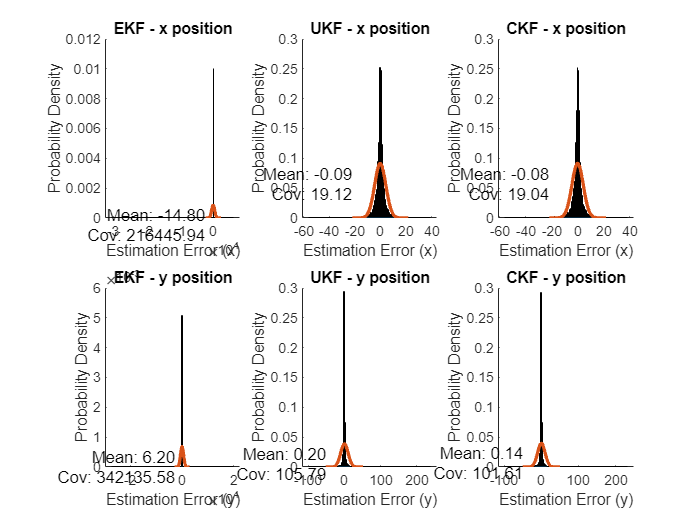

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (y)');
ylabel('Probability Density');
title('CKF - y position');
text(min(x), max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');